clc,clear,close all
% 设置微分方程
a = 1;
f = @(x,t) 2;   % 非其次量
g = @(x) sin(pi*x)+x.*(1-x);    % 初值
v1 = @(t) 0;     % 左边值
v2 = @(t) 0;    % 右边值
uu = @(x,t) exp(-pi^2*t)*sin(pi*x)+x.*(1-x);   % 解析解

% 设置求解区域
x0 = 0;
xm = 1;
T = 1;

% 设置差分方程的参数
tau = 0.0001;
h = 0.1;

% 迭代求解
lambda = tau/h^2;
if lambda*a>=1/2
    warning('算法不稳定')
end
n = round(T/tau)+1;
m = round((xm-x0)/h)+1;
u = zeros(n,m);
xx = x0:h:xm;
u(1,:) = g(xx);

for i = 2:n
        A1 = v1((i-1)*tau);
        A2 = a*lambda*u(i-1,1:end-2)+(1-2*a*lambda)*u(i-1,2:end-1)+a*lambda*u(i-1,3:end);
        A2 = A2+f(xx(2:end-1),(i-2)*tau)*tau;
        A3 = v2((i-1)*tau);
        temp = [A1,A2,A3];
    u(i,:) = temp;
end

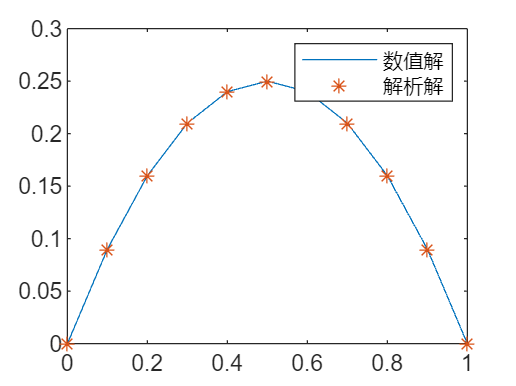

% 结果分析
plot(xx,u(end,:))
hold on
xx = x0:0.1:xm;
plot(xx,uu(xx,T),'*')
hold off
legend('数值解','解析解')